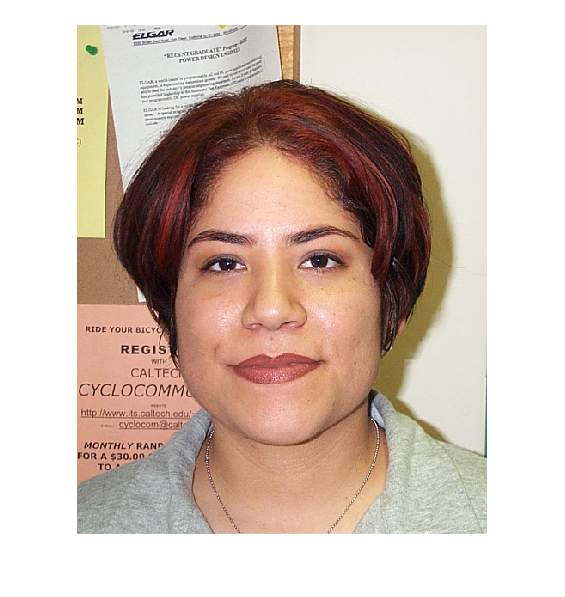

clear
picNumber = 1;
original = imread("..\db\DB0\db0_" + picNumber + ".jpg");
grayscale = im2gray(original);
eye_map = imread("eyeMask" + picNumber + ".png");
mouth_map = imread("mouthMask" + picNumber + ".png");
imshow(original)

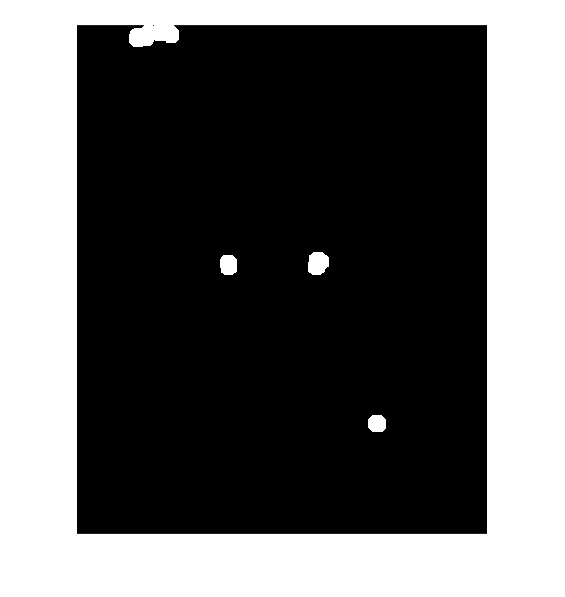


threshold_eye = 175;
eye_mask = eye_map > threshold_eye;
eyeSE = strel('disk',10);
eye_mask = imopen(eye_mask,eyeSE);
imshow(eye_mask)

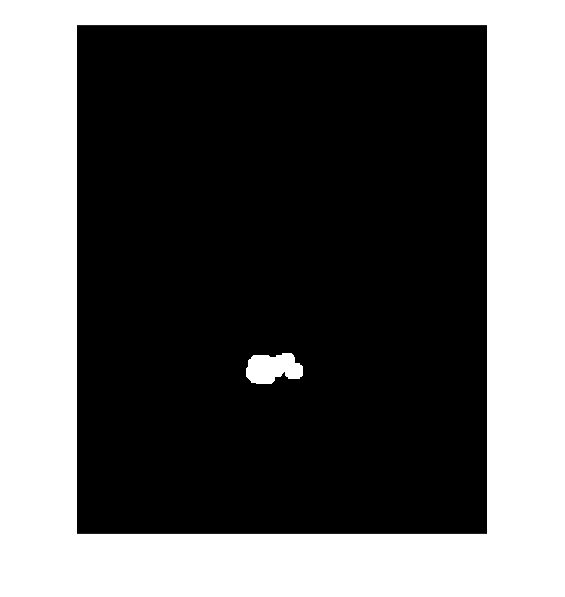


threshold_mouth = 3;
mouth_mask = mouth_map > threshold_mouth;
mouthSE = strel('disk',10);
mouth_mask = imopen(mouth_mask,mouthSE);
imshow(mouth_mask)

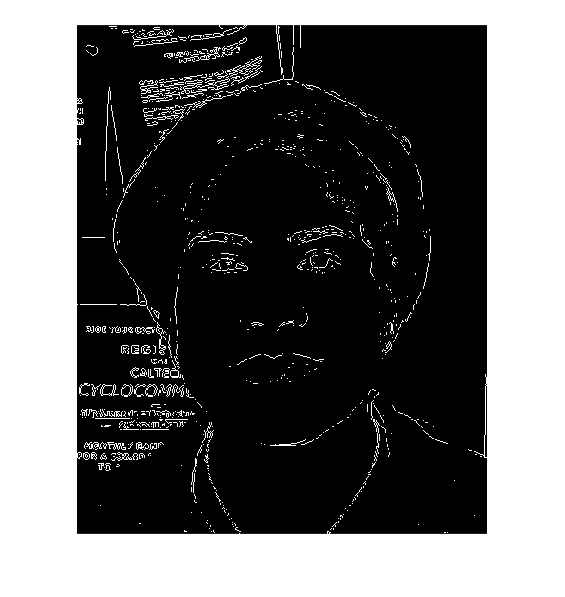



edges = edge(grayscale);
imshow(edges)

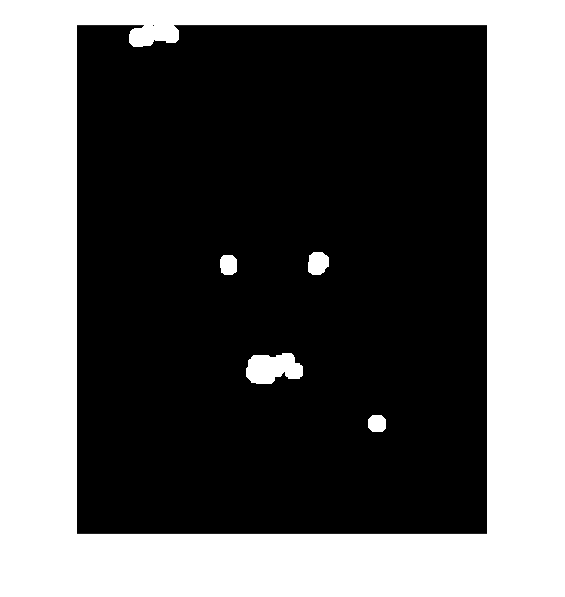


% faceMask = eye_mask | mouth_mask | edges;
faceMask = eye_mask | mouth_mask;

imshow(faceMask)


minSize = 80;
bw = bwareaopen(faceMask,minSize);

[B,L] = bwboundaries(bw,"noholes");

imshow(label2rgb(L,@jet,[.5 .5 .5]))

hold on
for k = 1:length(B)
  boundary = B{k};
  plot(boundary(:,2),boundary(:,1),"w",LineWidth=2)
end
title("Objects with Boundaries in White")

centerPoints = zeros(length(B),2);

y = zeros(1,length(centerPoints));
x = zeros(1,length(centerPoints));
for i = 1:length(centerPoints)
    [x(1,i),y(1,i)] = centroid(polyshape(B{i}(:,1),B{i}(:,2)));
end

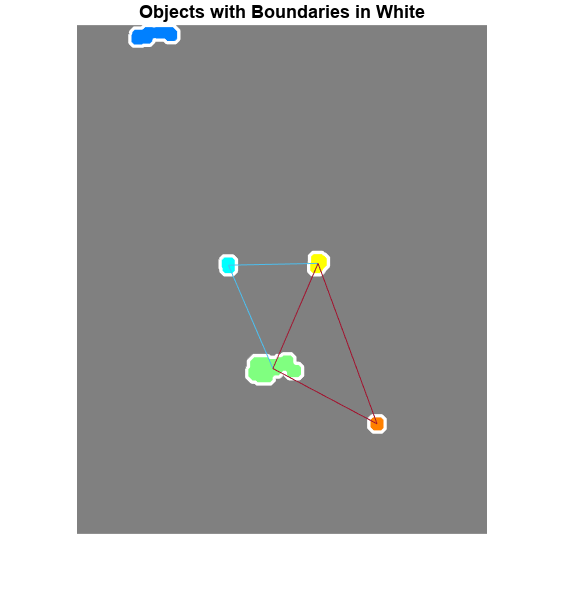



for i = 1:length(centerPoints)-2
    for j = i+1:length(centerPoints)-1
        for k = j+1:length(centerPoints)
            if isoscelesTriangleScore(x(i), y(i),x(j), y(j),x(k), y(k)) > 0.6
                plot([y(i) y(j) y(k) y(i)],[x(i) x(j) x(k) x(i)]);
            end
        end
    end
end